# Median Filter

A tiny tool to show its potentialities

## **Preliminary understanding**

In order to visualize in a proper fashion the effects of a median filter, it is asked the student to generate two sinusoids with very different frequency.

Their sum will have its discontinuities smoothed by applying a filter with parameter chosen.

#### **Choose the parameters of your sinusoid**:

amplitude = 88 ;
phase = 156;
phase = (phase*pi)/90;
frequency = 98;
duration  = 1;
Fs = 100;

time = 0:1/Fs:duration;

x = amplitude*cos(2*pi*frequency*time + phase);

#### Choose the parameters of the noise:

amplitude_n = -34 ;
phase_n = 42;
phase_n = (phase_n*pi)/90;
frequency_n = 54;

disturbance = amplitude_n*cos(2*pi*frequency_n*time + phase_n);

y = x + disturbance;

#### **Define the median filter**

For the implementation of the median filter, just choose its length:

d_parameter = 15;

y_restored = medfilt1(y, d_parameter);

#### **And here are the results!**

Figure comparison:

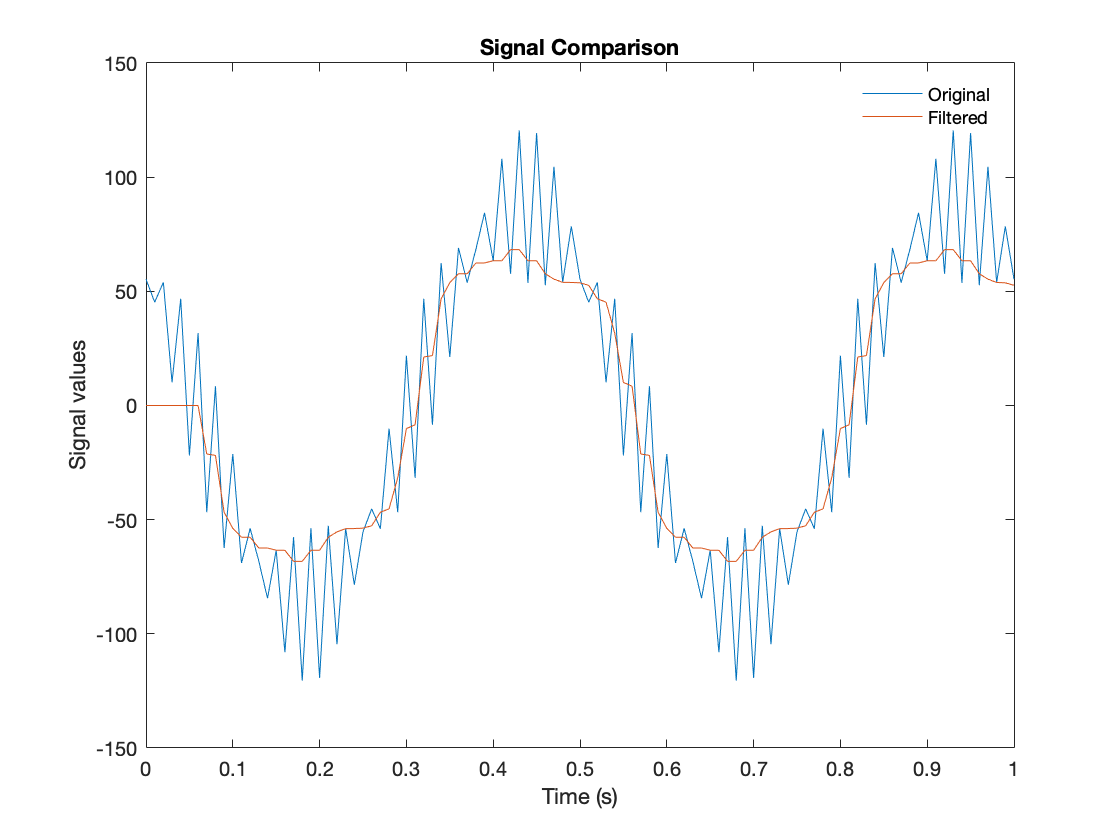

plot(time, y, time, y_restored)

title('Signal Comparison')
xlabel('Time (s)');
ylabel('Signal values')
legend('Original', 'Filtered')
legend('boxoff')

## Practical use: audio click smoothing

Now, instead of seeing the results, the student is going to hear the benefits of median filter with a proper example.

#### Choose the audio and the d parameter:

[music_signal, F_s] = audioread('iPhoneMarimba.wav'); 

t_max = 7; %max seconds of the signal, in order not to have overlappings during play
music_signal = music_signal(1:(t_max*F_s));

d_audio_parameter = 17;
music_restored = medfilt1(music_signal, d_audio_parameter);

### Signal comparison:

The results are shown both in a visual and in a hearing fashion.

#### Visual comparison:

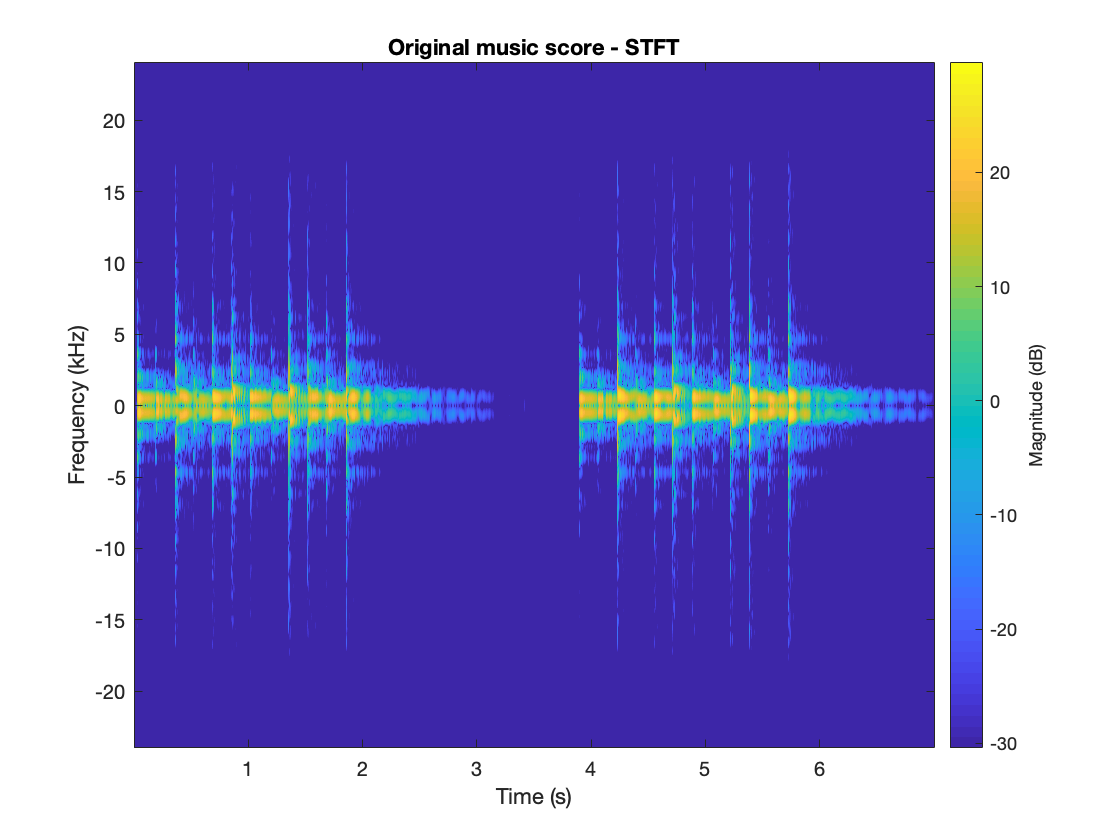

close

stft(music_signal, F_s, 'Window', hann(128), 'OverlapLength', 128/2,'FFTLength', 2048)
title('Original music score - STFT')

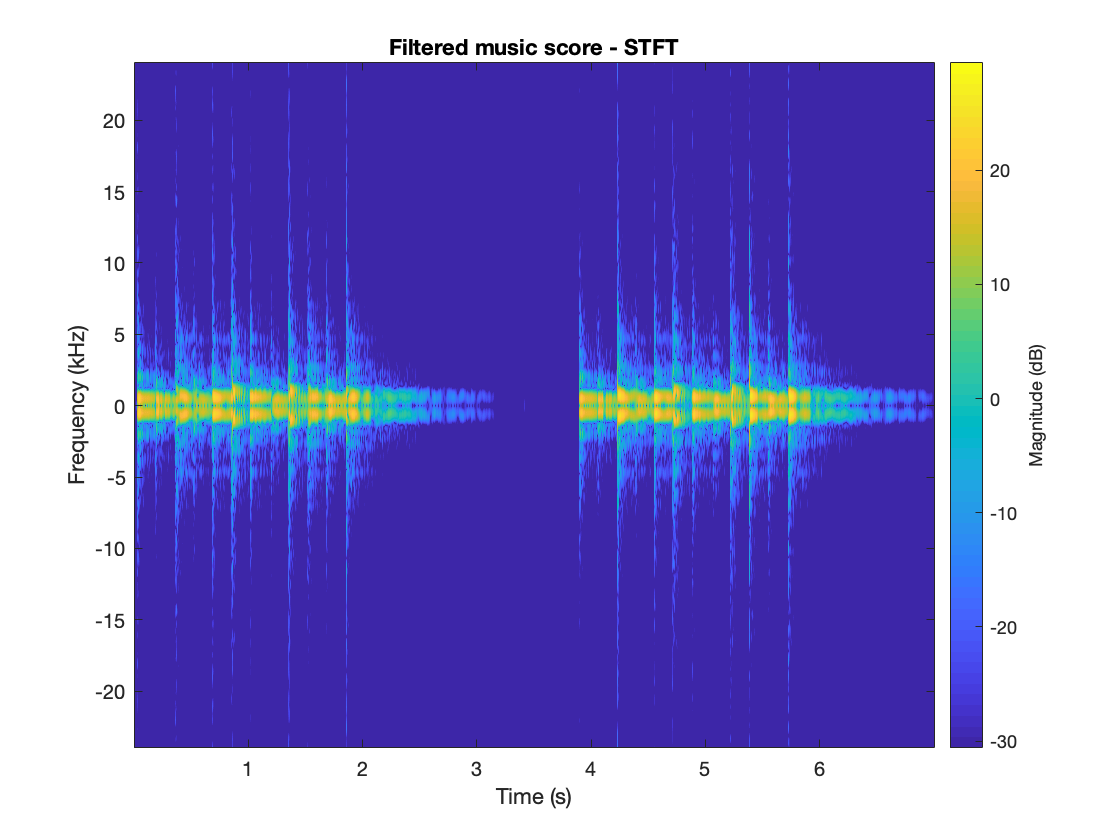

stft(music_restored, F_s, 'Window', hann(128), 'OverlapLength', 128/2,'FFTLength', 2048)
title('Filtered music score - STFT')

#### Hearing comparison:

(press play to listen)

 

soundsc(music_signal, F_s)

pause(10)

soundsc(music_restored, F_s)